# V768 - Measuring Vision with Psychophysics

## Lab 3 - Forced Choice Experiments

This lab ...

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Describe a psychometric curve.

- Explain why some psychometric curves have a floor of 0% and others have a floor of 50%.

- Describe the parameters of a psychometric curve (mu, sigma, lower lapse rate, and upper lapse rate).

### Questions

- ...

- Are yes/no and forced choice experiments measuring the same thing? Explain the similarities and differences.

## A. Method of Constant Stimuli

### Step 1. Data collection

In the first lab, you collected data using the PsychoPy experiment file "method-of-constant-stimuli.psyexp", so you've already completed data collection for this part of the lab!

### Step 2. Load your data

*(Reminder: PsychoPy will save your experiment data to a "data" folder inside of the same folder as the ".psyexp" file. The filename will start with the subject ID you used and end with the date/time of data collection.)*

Find the name of the ".csv" file containing your experiment data, and enter it below. Then run this section of code.

% change the filename to the one you generated during data collection
filename = '../01-classical-methods/method-of-constant-stimuli/data/demo_method_of_constant_stimuli_2025-01-06_16h02.30.014.csv';

% load the data table
detection_data = readtable(filename);

*(Reminder: Ignore the 'VariableNamingRule' warning.)*

% remove the rows/columns associated with the instructions in psychopy
detection_data(1,:)=[];
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
detection_data(:,remove) = [];

### Step 3. Analyze your data

For this experiment, PsychoPy saved the stimulus contrast and the participant's response per trial. The responses were stored as 'up' (stimulus present) or 'down' (stimulus not present).

% convert the response key to true for up and false for down
detection_data.response = strcmp(detection_data.response_keys,'up');

#### Find percentage of stimuli reported present (up), as a function of contrast

% average across responses per contrast level
analysis_table = table(detection_data.response, detection_data.contrast, ...
    'VariableNames',["response","contrast"]);
detection_results = grpstats(analysis_table,'contrast');

#### Plot responses as a function of contrast

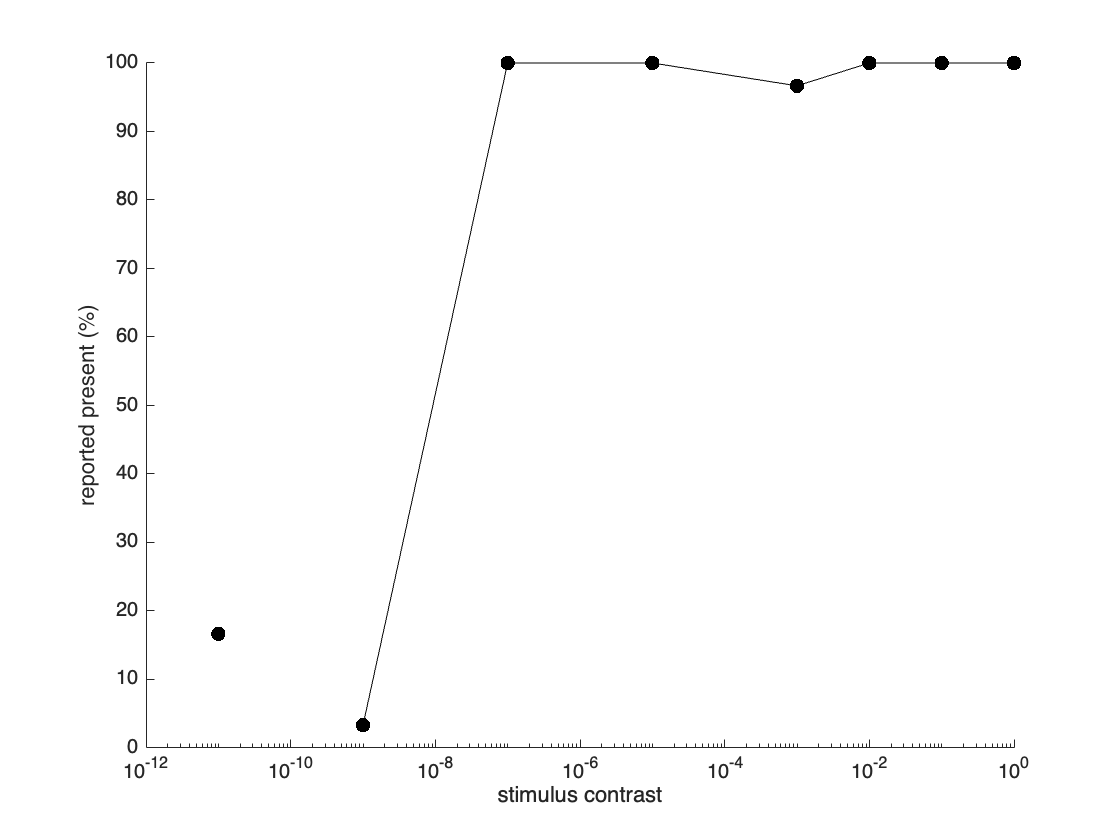

figure(1); clf; hold on;

% plot with stimulus contrast on a log scale
% (trials with zero contrast will not be included)
plot(detection_results.contrast,detection_results.mean_response*100,'k.-','MarkerSize',20)
set(gca,'XScale','log')
xlabel('stimulus contrast')
ylabel('reported present (%)')

% add a dot for zero contrast (blank) trials
plot(1e-11,detection_results.mean_response(1)*100,'k.','MarkerSize',20)

## Part B. Two-Alternative Forced Choice (2AFC)

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "forced-choice", and run that experiment. The instructions will appear on the screen before the trials begin. The experiment includes 240 trials.

### Step 2. Load your data

PsychoPy will save your experiment data to a "data" folder (inside of the same folder as the ".psyexp" file). The filename will start with the subject ID you used and end with the date/time of data collection.

Find the name of the ".csv" file containing your experiment data, and enter it below. Then run this section of code.

Before running this section of code, find the name of the ".csv" file containing your experiment data, and enter it below.

% change the filename to the one you generated during data collection
filename = 'forced-choice/data/demo_forced_choice_2025-01-06_23h01.49.058.csv';

% load the data table
choice_data = readtable(filename);

*(Reminder: Ignore the 'VariableNamingRule' warning.)*

% remove the rows/columns associated with the instructions in psychopy
choice_data(1,:)=[];
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
choice_data(:,remove) = [];

### Step 3. Analyze your data

For this experiment, the stimulus was a sinusoidal grating with a Gaussian mask. The grayscale luminance range in PsychoPy is -1 to 1, where -1 is black, 1 is white, and 0 is middle gray. The background luminance was set to 0. Thus, if the stimulus contrast were 0, the grating would be middle gray (the same luminance as the background), and if the stimulus contrast were 1, the grating's luminance would range from black to white.

PsychoPy saved the stimulus contrast, stimulus location (1 = right; -1 = left), and the participant's response per trial. The responses were stored as 'left' or 'right'.

trials = 1:size(choice_data,1);

% extract the stimulus's contrast level and location
stim_contrast = choice_data.contrast;
stim_location = choice_data.location;

% extract the response data
resp_key = choice_data.response_keys;

% convert the response key to 1 for right and -1 for left
% (to match stimulus location)
resp_location = double(strcmp(resp_key,'right'));
resp_location(resp_location==0) = -1;

#### Visualize the response per trial

Plot each trial's stimulus contrast, along with an indicator of ...

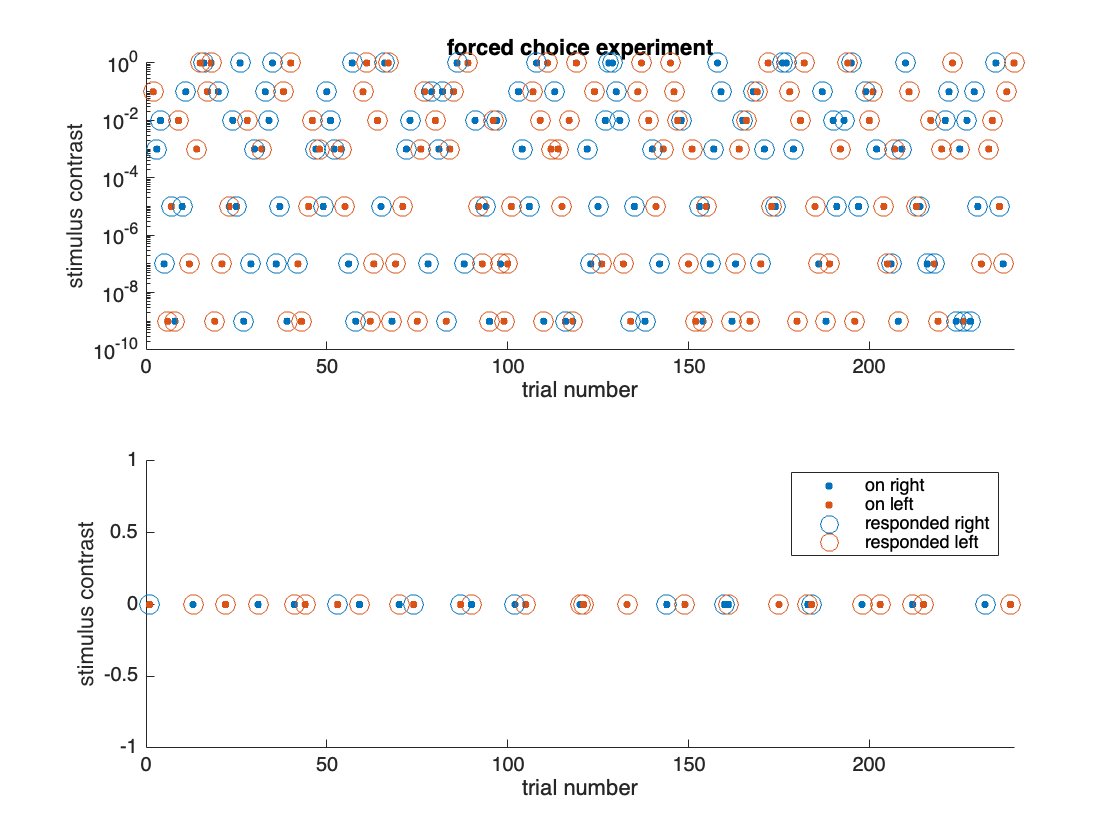

figure(2); clf;
colors = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];

% first, plot the stimulus contrast on a log scale
% (trials with zero contrast will not be included)
subplot(211); hold on;
plot(trials(stim_location==1), stim_contrast(stim_location==1), ...
    '.', 'MarkerSize',10);  % stimuli on the right
plot(trials(stim_location==-1), stim_contrast(stim_location==-1), ...
    '.', 'MarkerSize',10);  % stimuli on the left
set(gca,'YScale','log')
xlabel('trial number'); xlim([0,240])
ylabel('stimulus contrast')
title('forced choice experiment')

% add circles indicating the participant's response
plot(trials(resp_location==1), stim_contrast(resp_location==1), ...
    'o', 'MarkerSize',10, 'Color',colors(1,:));  % responsed on the right
plot(trials(resp_location==-1), stim_contrast(resp_location==-1), ...
    'o', 'MarkerSize',10, 'Color',colors(2,:));  % responded on the left

% second, plot the zero contrast trials (1/8th of the trials)
subplot(212); hold on;
was_zero = stim_contrast==0;
plot(trials(was_zero & stim_location==1), ...
    stim_contrast(was_zero & stim_location==1), ...
    '.', 'MarkerSize',10);  % stimuli on the right
plot(trials(was_zero & stim_location==-1), ...
    stim_contrast(was_zero & stim_location==-1), ...
    '.', 'MarkerSize',10);  % stimuli on the left
xlabel('trial number'); xlim([0,240])
ylabel('stimulus contrast')

% add circles indicating the participant's response
plot(trials(was_zero & resp_location==1), ...
    stim_contrast(was_zero & resp_location==1), ...
    'o', 'MarkerSize',10, 'Color',colors(1,:));  % responsed on the right
plot(trials(was_zero & resp_location==-1), ...
    stim_contrast(was_zero & resp_location==-1), ...
    'o', 'MarkerSize',10, 'Color',colors(2,:));  % responded on the left
legend('on right', 'on left', 'responded right', 'responded left')

#### Determine whether responses were correct or incorrect

% do stimulus and response locations match?
resp_correct = stim_location == resp_location;

% display results
fprintf('Percentage correct = %.2f%%\n', mean(resp_correct)*100);

Percentage correct = 84.17%


#### Determine percentage correct per contrast level

% average across responses per contrast level
analysis_table = table(resp_correct, stim_contrast, ...
    'VariableNames',["response","contrast"]);
choice_results = grpstats(analysis_table,'contrast');

#### Plot percentage correct as a function of contrast

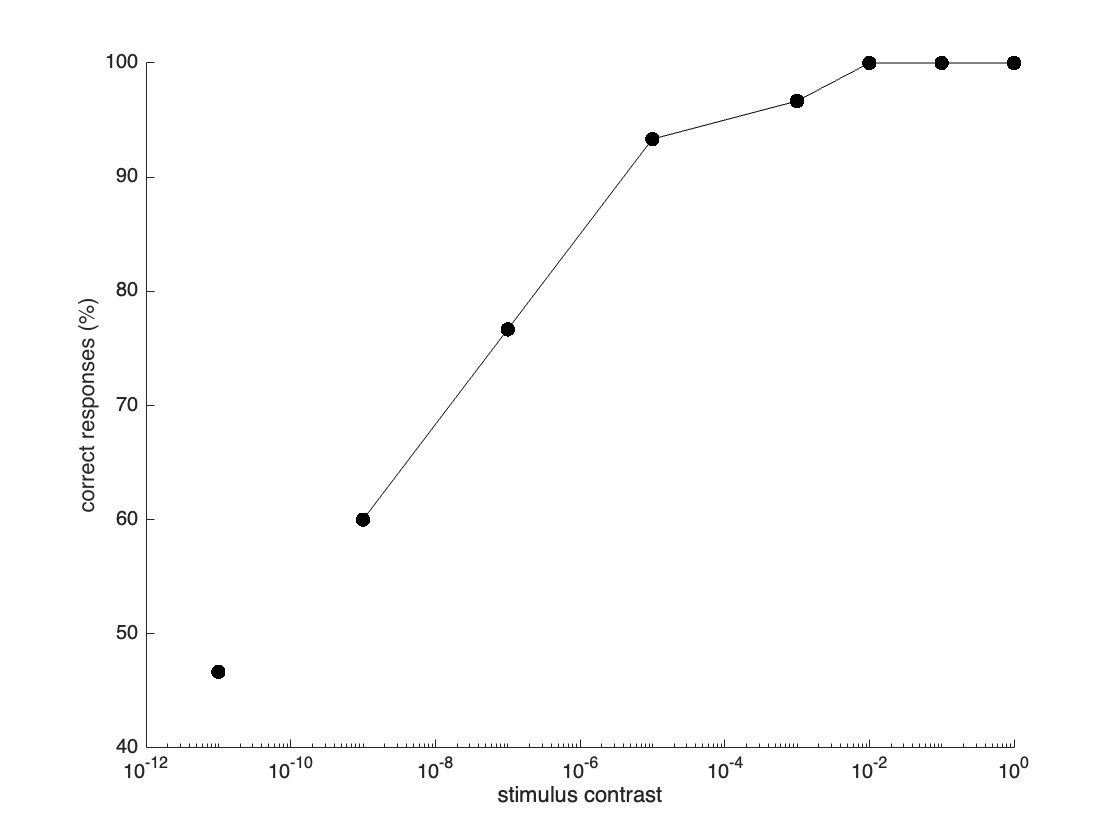

figure(3); clf; hold on;

% plot with stimulus contrast on a log scale
% (trials with zero contrast will not be included)
plot(choice_results.contrast,choice_results.mean_response*100,'k.-','MarkerSize',20)
set(gca,'XScale','log')
xlabel('stimulus contrast')
ylabel('correct responses (%)')

% add a dot for zero contrast (blank) trials
plot(1e-11,choice_results.mean_response(1)*100,'k.','MarkerSize',20)

## Part C. Compare Signal Detection (Yes/No) and 2AFC Experiments

### Step 1. Compare performance

...

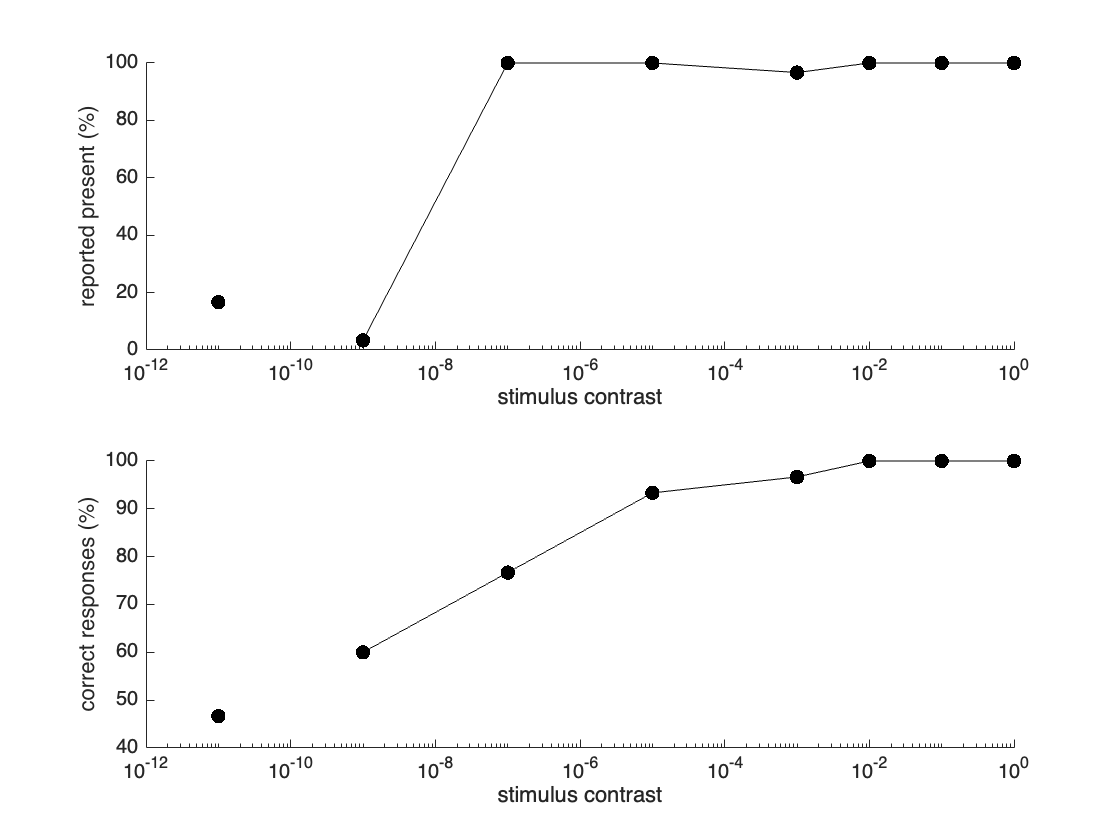

figure(4); clf;

% plot signal detection results
subplot(211); hold on;
plot(detection_results.contrast,detection_results.mean_response*100,'k.-','MarkerSize',20)
plot(1e-11,detection_results.mean_response(1)*100,'k.','MarkerSize',20)
set(gca,'XScale','log')
xlabel('stimulus contrast')
ylabel('reported present (%)')

% plot forced choice results
subplot(212); hold on;
plot(choice_results.contrast,choice_results.mean_response*100,'k.-','MarkerSize',20)
plot(1e-11,choice_results.mean_response(1)*100,'k.','MarkerSize',20)
set(gca,'XScale','log')
xlabel('stimulus contrast')
ylabel('correct responses (%)')

## Part D. Fit a psychometric curve

% define psychometric function to fit
cdfFxn = @(c,x) normcdf(x, c(1), c(2));
c0 = [0 1];  % starting values

% suppress lsqcurvefit auto-printing
% (e.g., "Local minimum found. Optimization completed because the size of
% the gradient is less than the value of the optimality tolerance.
% <stopping criteria details>")
opts = optimset('Display','off');

% fit function to data
[C] = lsqcurvefit(cdfFxn, c0, ...
    x_vals, ...  % x values of psychometric curve
    y_vals, ...  % y values of psychometric curve
    [],[], opts);
                
% extract function parameters
fit_mu = C(1);
fit_sigma = C(2);